clc
clear
close all; 

% Part D 
k = [20 12 8 8 4 4];
dmin = [2 2*sqrt(2) 4 2*sqrt(5) 6 2*sqrt(10)];
alpha = k/24;
beta = dmin.^2./4;
syms alpha_i beta_i
disp(alpha_i)

$$\alpha_{i}$$

disp(alpha)

    0.8333    0.5000    0.3333    0.3333    0.1667    0.1667



disp(beta_i)

$$\beta_{i}$$

disp(beta)

    1.0000    2.0000    4.0000    5.0000    9.0000   10.0000



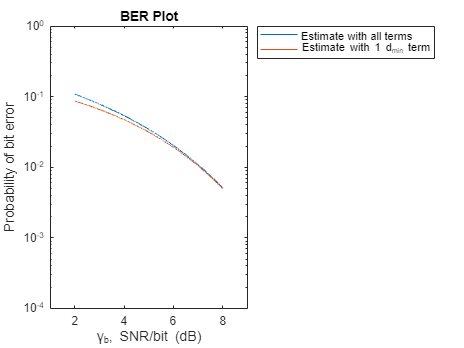

% Part F 
gamma = linspace(2, 8, 10000);
gamma = 10.^(gamma/10);

Perr_all = zeros(size(gamma));

for i = 1:6
    y = 1/24 * k(i) * qfunc(sqrt(beta(i)*gamma));
    Perr_all = Perr_all + y;
end

Perr_one = 1/24 * 20 * qfunc(sqrt(gamma));
gamma = 10*log10(gamma);

figure
semilogy(gamma, Perr_all);
hold on
semilogy(gamma, Perr_one);
ylim([10^(-4) 1])
xlim([1 9])
title("BER Plot")
xlabel("\gamma_b, SNR/bit (dB)")
ylabel("Probability of bit error")
legend("Estimate with all terms", "Estimate with 1 d_{min} term", "location","bestoutside")


fprintf("Ratio : 1 - Perr,only one term/Perr,all terms")

Ratio : 1 - Perr,only one term/Perr,all terms

ratio = 1-Perr_one(1)/Perr_all(1);
fprintf("Ratio Value at 2dB = %d", ratio);

Ratio Value at 2dB = 1.991140e-01

ratio = 1-Perr_one(10000)/Perr_all(10000);
fprintf("Ratio Value at 8dB = %d", ratio);

Ratio Value at 8dB = 1.873659e-02